# Neural Networks

## What are neural networks?

**Neural networks** are a set of algorithms that were inspired by neural circuits in the brain, and have exploded in popularity due to advances in computing technology. These algorithms use information from the most informative features in the dataset from a series of linear and nonlinear transformations to optimize two parameters. These two parameters can then be applied to other datasets for inference.

Neural networks are powerful algorithms that can be applied to complex problems with dynamic features. We'll first use a synthetic dataset to demonstrate the concepts and mathematics underpinning a simple neural network. Then we'll work on building our own neural network and analyze the Framingham dataset. In the next lecture, we'll use neural networks to train a classifier on breast cancer imaging dataset to predict the degree of progression.

### The components and notation of a neural network

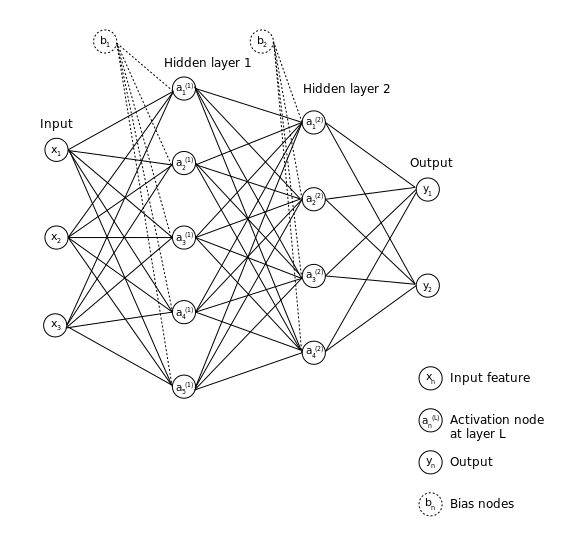

There are several flavors of neural network architectures, each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, a base model that contains the principles needed to understand how neural networks work generally. These principles can then be applied to construct other neural network variations. 

**Each component is described below:**

Input layer: the data ($X_{\textrm{train}}$) we are training the neural network on, where each $n^{\textrm{th}}$ column or feature vector represents a node in the network digram. The diagram above shows 3 features in the input layer.

Hidden layer(s): where the features are transformed into new data representations via linear and non-linear transformations

- Each **activation node** ($a_n$) represents our newly determined complex feature vector. A single hidden layer can consist of several activation nodes that may not necessarily correspond to the number of predictors we are inputting into the model. 

- The **bias nodes** ($b_n$) can be a scalar or vector of values that further influences the model fit. 

Output layer: the final computed values after processing the input data through the hidden layers. 

The diagram above shows a neural network containing two hidden layers - these are considered to be **deep neural networks **if there are multiple hidden layers. 

To illustrate the basic computations, however, we'll only be dealing with a **shallow neural network** that contains only 1 hidden layer.

## Training a neural network using forward propagation

The training phase of a neural network is called **forward propagation**, and consists of iteratively performing a linear transformation and non-linear transformation until we reach the output layer. 


$$X_{\textrm{train}} \to^{\textrm{Linear}} Z\to^{\textrm{Nonlinear}} A\to^{\textrm{Repeat}\;n\;\textrm{times}} \;y_{\textrm{pred}}$$


### Step 1: Linear transformation 

Let's consider our artificial dataset, which consists of 50 observations and 6 features. 

% Initialize inputs using random numbers from default seed
rng('default');
Xtrain          = normrnd(0, 1, [50, 6]);

**The first step in training a neural network is to perform a linear transformation of the data**, similar to what you've seen in the linear regression part of the course, to compute a new "feature". Because we only have 1 node, The formulation for the 6 features is the following equation:


$$\begin{array}{l}
z_1 ={1\cdot x}_1 +b\\
z_2 ={0\cdot x}_2 +b\\
\vdots \\
z_6 ={0\cdot x}_6 +b
\end{array}$$
 

The vectorized form of these equations can be written as:


$$Z=X^T w+b$$


$X$ has the features spanning the columns, and the observations span the rows. This is the same form as the linear regression problem. And just like our regression problem, we're learning two parameters: the **weights** ($w$) and the **bias** ($b$) values. 

Let's now compute how the two parameters $w$ and $b$ impact the solution $Z$, and then plot the relationship between `X` and `Z`:

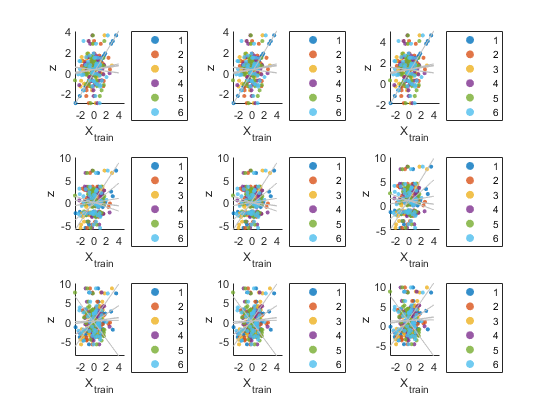

% Example with three different w and b vectors
wArray = [[1, 0, 0, 0,  0, 0]; ...   % One activation node
          [1, 0, 2, 0,  0, 0]; ...   % Two activation nodes
          [1, 0, 2, 0, -2, 0]];      % Three activation nodes

bArray = [zeros([50, 1]), ...        % All zeros
          randn([50, 1]) * 0.01, ... % Random values
          ones( [50, 1])];           % All ones

% Construct several values for Z
for i = 1:size(wArray, 1)
    for j = 1:size(bArray, 2)
        b       = bArray(:, j);
        w       = wArray(i, :);
        Z{i, j} = Xtrain * w' + b;
    end
end

% Plot Z with respect to each feature in X
figure;
markersize   = 10;
featureNames = ['1'; '2'; '3'; '4'; '5'; '6'];
positions    = [[1, 2, 3];
                [4, 5, 6];
                [7, 8, 9]];

for i = 1:size(Z, 1)
    for j = 1:size(Z, 2)
        subplot(3, 3, positions(i, j))
        hold on;
        
        for k = 1:size(Xtrain, 2)
            scatter(Xtrain(:, k), Z{i, j}, ...
                markersize, ...
                'filled', ...
                'MarkerFaceAlpha', 0.8);
        end
        
        hold off;
        lsline;
        legend(featureNames, 'location', 'bestoutside');
        
        xlabel('X_{train}');
        ylabel('z');
    end
end

From left to right, the biases are changing from all zeros, to random, to all ones. From top to bottom, the number of weights in the model vary from 1 to 3. 

### Step 2: Non-linear transformations using the Sigmoid activation function

**The second step involves transforming the data again using a non-linear function.** In this particular example, let's the sigmoid function. To review, data can be transformed to the characteristic 'S' curve using the following equation:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


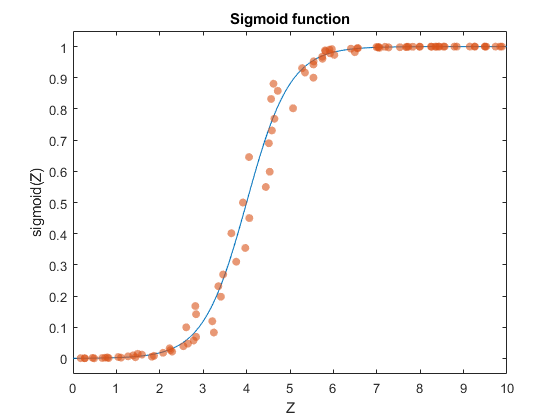

% Sigmoid distribution
figure;

Z = -5:0.1:5;
sigmoidZ = activationFnc(Z, 'Sigmoid');
plot(Z, sigmoidZ);
hold on;
scatter(Z, sigmoidZ, ...
    'filled', 'o',  ...
    'MarkerFaceAlpha', 0.6, ...
    'jitter', 'on', ...
    'jitterAmount', 0.5);
xlabel('Z');
ylabel('sigmoid(Z)');
xline(0);
ylim([-0.05, 1.05]);
title('Sigmoid function');

This function is useful for classification, especially if we're trying to predict two possible outcomes (a binary classification problem). This is due to the base `e` term in the denominator, which will either make the value `A` approach 0 if $z_i$ is large, or 1 if$z_i$ was small.

To implement the sigmoid function in MATLAB, we can use the `activationFnc` function provided in the project folder. Shown below are the relevant parts of the function used to transform the data using a sigmoidal function:

Let's now transform our `Z` array using the sigmoid function and see the results of the transformation:

% Compute A using the Z cell array
for i = 1:size(Z, 1)
    for j = 1:size(Z, 2)
        A{i, j} = activationFnc(Z{i, j}, 'Sigmoid');
    end
end

% Plot A with respect to the first feature in Xtrain
figure;
markersize   = 10;
featureNames = ['1'; '2'; '3'; '4'; '5'; '6'];
positions    = [[1, 2, 3]; ...
                [4, 5, 6]; ...
                [7, 8, 9]];

for i = 1:size(A, 1)
    for j = 1:size(A, 2)
        subplot(3, 3, positions(i, j))
        hold on;
        
        scatter(Xtrain(:, 1), A{i, j}, ...
                markersize, ...
                'filled', ...
                'MarkerFaceAlpha', 0.8);
        
        hold off;
        b = gca;
        legend(b, 'off');
        
        xlabel('X_{train}');
        ylabel('A');
    end
end

From left to right, the biases are changing from all zeros, to random, to all ones. From top to bottom, the number of weights in the model vary from 1 to 3. As we add more weights, the features tend to become more complex and tend to not follow a given distribution. However, a clearer decision boundary starts to form, and several values start to assume a value of either 1 or 0. 

### A full round of forward propagation

Let's now put all of these concepts together to run a full round of forward propagation with a real dataset. 

The `ovariancancer` dataset contains 4000 proteomics predictors with 216 patients that either have cancer (n = 121), or are healthy (n = 95). We'll build a neural network classifier that will predict whether they are normal or healthy.

% Clear existing workspace if you haven't already
clear all;

% Load the ovarian cancer dataset (built-in MATLAB dataset)
load ovariancancer.mat;

% FOR LABELS: Let cancer = 1 and normal = 0
grp = strrep(grp, 'Cancer', '1');
grp = strrep(grp, 'Normal', '0');
grp = cellfun(@(x) str2double(x), grp);

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(obs, grp, 0.8, true);

To keep the network relatively simple, we'll use 10 activation nodes. With these 10 activation nodes, we'll randomly choose values for `w` and `b. L`ater we'll discuss why this random initialization is important for both the weights and the biases.

rng('default');

% Weights and biases for input -> hiddent
w1 = randn([size(Xtrain, 2), 10]) * 0.01;
b1 = randn([size(Xtrain, 1), 1]);

Let's now run forward propagation, first from the input layer to the hidden layer:

% Run forward propagation for input -> hidden
Z1 = Xtrain * w1 + b1;
A1 = activationFnc(Z1, actFnc);

Now we need to run forward propagation one more time, from the hidden layer to the output layer. We will use the values `A1` as the input for this round. Additionally, we will not bias our answers in this layer:

% Weights for hidden -> output
w2 = rand(10, 1) * 0.01;

% Run forward propagation for hidden -> output
Z2 = A1 * w2;
A2 = activationFnc(Z2, actFnc);

% Since we've made our way to the output layer, A2 is our final predicted y
% value
ypred = A2;

That's a full round of forward propagation! Now we need to now see how well our model performed using a cost function.

## Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through. We can do that using a cost function. Because we are performing a classification problem, we can use the Cross-Entropy cost function.

#### **Cross-Entropy cost function**

For the case where we are performing a classification problem, we can use the **Cross-Entropy (aka Log-Loss) cost function:**


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


$m$ = number of observations

$y_{\textrm{train}}$ = the response variable

$y_{\textrm{pred}}$ = the predicted value for$y_{\textrm{train}}$ from forward propagation

The **cost** value can be computed using the code from the `costFunction.mlx` script, which defines the cost function as follows:

To review, let's get the cost for first round of feed-forward propagation:

J = costFunction(Ytrain, ypred); % J should equal 0.6877

## Optimizing neural network parameters using backward propagation

Finally, after computing the cost, we need to adjust the model parameters (`w` and `b)` until the error is below a given threshold or after a certain number of iterations. This can be done using an optimization algorithm we covered earlier in the course called gradient descent. To use gradient descent however, we need to **back propagate** and find the specific weights / biases that need to be changed to minimize the cost. 

### Optimizing parameters `W` and `b` using gradient descent

To review, the objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters, we have two equations to update:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\alpha \cdot \textrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}-\left(\alpha \cdot \textrm{db}\right)
\end{array}$$
 

$\alpha$ is the learning rate hyperparameter

### Finding dW and db using back propagation

To compute the gradient for `W` and `b` (`dW` and `db`), we need to see which weights and biases contribute the highest cost, starting from the output layer to the input layer and compute the gradient - that is, how should the `w` be increased or decreased to reduce the cost.

We can set this up as two differential equations to get the gradient:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

And ideally, we would work these chains of differential equations out for each layer, and each component of the neural network we computed. After working out the differential equations, we get the following set of derivatives that are needed to compute `dW2`, `dW1`, and `db1.`

**Back propagating from the output layer to the hidden layer:**


$$\begin{array}{l}
\textrm{dZ2}=-\left(\frac{y_{\textrm{train}} }{y_{\textrm{pred}} }-\frac{1-y_{\textrm{train}} }{1-y_{\textrm{pred}} }\right)\\
d\textrm{W2}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ2}\cdot \textrm{A2}\right)
\end{array}$$


**Backpropagating from the hidden layer to the input layer:**


$$\begin{array}{l}
\textrm{dZ1}=\textrm{W2}\cdot \textrm{dZ2}\cdot g^{\prime } \left(\textrm{Z1}\right)\\
d\textrm{W1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\cdot \textrm{A1}\right)\\
\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)
\end{array}$$


Note that the derivative of the sigmoid function is $g^{\prime } \left(\mathrm{Z1}\right)\;=\;\mathrm{sigmoid}\left(\mathrm{Z1}\right)\cdot \left(1-\mathrm{sigmoid}\left(\mathrm{Z1}\right)\right)$. This is equivalent to $g^{\prime } \left(\mathrm{Z1}\right)\;=\;\left(1-{\mathrm{A1}}^2 \right)$, which will be the expression we'll use to get `dZ1.`

### A full round of back propagation

Now let's codify the expressions above to run a full round of back propagation:

% Initialize constants that will be used in the following expressions
alpha = 0.05;
m = size(Xtrain, 1);

First let's back propagate from the output layer to the hidden layer:

% Back propagation from output layer back to hidden layer
dZ2 = ypred - Ytrain;
dW2 = (1/m) * (A1 * dZ2);

Next let's back propagate from the hidden layer to the input layer:

% Back propagation from hidden layer to the input layer
dZ1  = (dZ2 * w2') .* (1 - A1.^2)';
dW1  = (1/m) .* dZ1' * X;
db1  = (1/m) .* sum(dZ1, 2);

And finally, let's update the values using gradient descent:

% Update w2, w1, and b1 using the gradients we just computed
w2 = w2 - (alpha .* dW2);
w1 = w1 - (alpha .* dW1);
b1 = b1 - (alpha .* db1);

We have successfully back propagated to get better values for `W` and `b. `To train the neural network even more, we would iterate the entire process of forward propagation, computing the cost, and backward propagation several times until the `w` and `b` values converge to a stable value. 

## Running the neural network for the ovarian cancer data set

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, let's create a single function that can perform all the computations. Below is a function for the shallow neural network that contains all of the code we have written so far. While it does look daunting, each comment for each block of code refers to the calculations we made in previous sections.

The only difference between our code and the current code is that the values that are of interest to us are stored in the MATLAB `structure` outputted from this function. Further documentation is included in the `SNN`.mlx MATLAB livescript.

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the ovarian cancer dataset:

% Clear existing workspace if you haven't already
clear all;

% Load the ovarian cancer dataset (built-in MATLAB dataset)
load ovariancancer.mat;

% FOR LABELS: Let cancer = 1 and normal = 0
grp = strrep(grp, 'Cancer', '1');
grp = strrep(grp, 'Normal', '0');
grp = cellfun(@(x) str2double(x), grp);

% Split the dataset into training and test sets.

X = obs;
Y = grp;
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(X, Y, 0.8, true);

% Initialize other important model parameters 
numOfActiveNodes = 10;
alpha = 0.2;
iterations = 1000;
actFnc = 'Sigmoid';
randomstate = true;

% Run the neural network
[model] = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, iterations, actFnc, randomstate);

### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

% Plot of the cost:
plot(1:length(model.J), model.J);
title('Cost with \alpha = 0.05');
xlabel('Number of iterations');
ylabel('Cost (J)');

As you can see, while it appears that the model is approaching a minimum cost value, it looks like there is still room for improvement. Later on, we'll optimize the model hyperparameters as well to get the best shallow neural network model.

### Assessing model accuracy

#### Hold out accuracy

Next, let's use the test set to come up with a prediction. To do that using our neural network, we can use the following function from the `predict` script:

ypred = predict(model, Xtest, Ytest);

Now that we have a prediction from our neural network, we can evaluate the model accuracy. To do that, we need to transform the `ypred` field in the model to be either 0 or 1. For the decision boundary, let's use 0.5: if the value is greater than or equal to 0.5, we'll assign that index to 1, otherwise it's 0. We'll also plot the confusion matrix and report the hold out accuracy.

% Re-map to original labels
ypred(ypred >= 0.5) = 1;
ypred(ypred < 0.5) = 0;

% Plot confusion matrix
cm = confusionmat(Ytest, double(ypred));
    
figure;
labels = {'Cancer', 'Healthy'};
confusionchart(cm, labels);
title('Confusion matrix for SNN classification');

% Compute hold-out accuracy for each class and the average class accuracy
trueClass = sum(cm, 1);
cancerAcc = cm(1, 1) / trueClass(1);
healthyAcc = cm(2, 2) / trueClass(2);
averageClassAcc = sum(diag(cm)) / sum(trueClass);

The average accuracy across all classes is 79.55%, which is a decent score for a single hold out. Additionally, the accuracy for predicting cancer (70.83%) and healthy (90.00%) is pretty good as well.

#### Cross validation accuracy

Of course, the hold out accuracy itself is not necessarily the best measure to evaluate the neural network. Let's also run 10-fold cross validation and see how our model does on average. This is how we will compute the 10-fold cross validation accuracy on the trained neural network:

kfold = 10;
Summary = crossValidate(X, Y, model, kfold);

figure;
labels = {'Cancer', 'Healthy'};
confusionchart(Summary.cm, labels);
title('Confusion matrix from 10-fold cross validation');

The average accuracy across all classes is 81.45%, which is pretty good considering we did not even pursue further optimization of the hyperparameters yet. Additionally, the accuracy for predicting cancer (72.24%) and healthy (93.68%) is pretty high.

### Benchmarking against a linear model

Let's see how well our model performs against a simple ordinary least squares classifier. To train an OLS model, we can 

## Tuning neural network model components

### Other Activation functions

#### Rectified Linear Units (ReLU) Activation Function

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. In back propagation, the gradient becomes really small, resulting in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to learning model parameters.

- Further, our values are between 0 and 1. Because the values are not zero-centered, our algorithm becomes more difficult to optimize.

Thus, the formulation of the ReLU is as follows:


$$\begin{array}{l}
\mathrm{ReLU}\left(Z\right)=\mathrm{max}\left(0,\;Z\right),\\
\mathrm{where}\;A=\left\lbrace \begin{array}{cc}
\mathrm{max}\left(Z\right) & \mathrm{if}\;z\;\mathrm{is}\;\mathrm{positive}\\
0 & \mathrm{if}\;z\;\mathrm{is}\;\mathrm{negative}
\end{array}\right.
\end{array}$$


And the function has the following distribution:

% ReLU distribution
figure;
Z = -5:0.1:5;
ReLUZ = activationFnc(Z, 'ReLU');
plot(Z, ReLUZ);
hold on;
scatter(Z, ReLUZ, ...
    'filled', 'o',  ...
    'MarkerFaceAlpha', 0.6, ...
    'jitter', 'on', ...
    'jitterAmount', 0.10);
xlabel('Z');
ylabel('ReLU(Z)');
xline(0);
ylim([-0.05, 1.05]);
title('ReLU function');

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- All of the negative values have a derivative value of 0, while for positive values, the derivative is 1. Thus, this rectifies the vanishing gradient problem.

- It is also computationally economical, and easy to optimize.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

To implement the ReLU using MATLAB, we can use the `activationFnc` function, using `ReLU` as the second argument:

The ReLU is not a magic bullet, and there are limitations to it, despite it being a better activation function than other alternatives:

- For values of Z < 0, the gradient will be 0 because the weights will not get adjusted during gradient descent. Thus, these neurons will not respond to back propagation. This is known as the **dying ReLU problem**.

#### Leaky ReLU Activation Function

To counteract the dying ReLU problem, the following solution has been proposed: instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus prevents the information loss from the ReLU.

The formulation for the leaky ReLU is


$$\mathrm{Leaky}\;\mathrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \mathrm{if}\;z\;\mathrm{is}\;\mathrm{positive}\\
\varepsilon \cdot z & \mathrm{if}\;z\;\mathrm{is}\;\mathrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution:

% Leaky ReLU distribution
figure;

Z = -5:0.1:5;
LeakReLUZ = activationFnc(Z, 'Leaky ReLU', 0.01);

plot(Z, LeakReLUZ);

hold on;
scatter(Z, LeakReLUZ, ...
    'filled', 'o',  ...
    'MarkerFaceAlpha', 0.6, ...
    'jitter', 'on', ...
    'jitterAmount', 0.10);

title('Leaky ReLU function');
xlabel('Z');
ylabel('Leaky ReLU(Z)');
xline(0);
yline(0);
ylim([-0.05, 1.05]);

To implement the Leaky ReLU using MATLAB, we can use the `activationFnc` function, using `Leaky` `ReLU` as the second argument. Additionally, we can specify the scaling factor $\varepsilon$ as the third argument. The default value for $\varepsilon$ is 0.01:

Finally, let's compare three neural networks that use all three different activation functions, and see which one performs the best:

% Train the 3 models
model1 = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, iterations, 'Sigmoid', randomstate);
model2 = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, iterations, 'ReLU', randomstate);
model3 = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, iterations, 'Leaky ReLU', randomstate);

% Plot the cost curves:
figure;
plot(1:length(model1.J), model1.J); hold on;
plot(1:length(model2.J), model2.J); hold on;
plot(1:length(model3.J), model3.J); hold on;
title('Cost with \alpha = 0.05');
xlabel('Number of iterations');
ylabel('Cost (J)');


### Optimizing the learning rate

Now that we have all the pieces we need to construct our neural network, let's put it into practice. 

We can play with the 

{Image of J(W) w.r.t W }

{Confusion matrix for final results after n iterations}

## Summary

We have gone over how to train a neural network from scratch, which can be summarized below:

- **Intialize weights** for each connection between nodes in different layers

- **Forward propagation:** Feed the input data $X_{\textrm{train}}$ into the neural network, and for each $L^{\textrm{th}}$ layer, scale the data with weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, while transforming the scaled data with an activation function $g\left(\cdot \right)$ until we reach the output layer.

- **Use the cost function **to compute the cost $J$, or the error between the predicted output value of the $i^{\textrm{th}}$ iteration and the actual response variable value $y_{\textrm{train}}$.

- **Backpropagation using gradient descent**: Using the cost with respect to weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, optimize each parameter by moving backward through the network.

- **Repeat** $i$ times until the costs $J$ reach the minimum value or you have reached the number of iterations allotted in the `for` loop. 